# Correct Symbol Timing Error of BPSK-Modulated Signal

Correct a fixed symbol timing error on a noisy BPSK transmission signal. Check the bit error rate (BER) of the synchronized received signal.

Initialize simulation parameters.

clear;clc;close all
M = 2;         % Modulation order for BPSK
nSym = 20000;  % Number of symbols in a packet
sps = 4;       % Samples per symbol
timingErr = 2; % Samples of timing error
snr = 15;      % Signal-to-noise ratio (dB)

Create root raised cosine (RRC) transmit and receive filter System objects.

txfilter = comm.RaisedCosineTransmitFilter(...
    'OutputSamplesPerSymbol',sps);
rxfilter = comm.RaisedCosineReceiveFilter(...
    'InputSamplesPerSymbol',sps,'DecimationFactor',1);

Create a symbol synchronizer System object™ to correct the timing error.

symbolSync = comm.SymbolSynchronizer(...
    'SamplesPerSymbol',sps, ...
    'NormalizedLoopBandwidth',0.01, ...
    'DampingFactor',1.0, ...
    'TimingErrorDetector','Gardner (non-data-aided)');

Generate random data symbols and apply BPSK modulation.

data = randi([0 M-1],nSym,1);
modSig = pskmod(data,M);

Create a delay object to introduce a fixed timing error of 2 samples. Because the transmit RRC filter outputs 4 samples per symbol, 1 sample is equivalent to a 1/4 symbol through the fixed delay and channel.

fixedDelay = dsp.Delay(timingErr);
fixedDelaySym = ceil(fixedDelay.Length/sps); % Round fixed delay to nearest integer in symbols

Filter the modulated signal through a transmit RRC filter by using the `txfilter` object. Apply a signal timing error by using the `fixedDelay` object.

txSig = txfilter(modSig);
delayedSig = fixedDelay(txSig);

Pass the delayed signal through an AWGN channel.

rxSig = awgn(delayedSig,snr,'measured');

Filter the modulated signal through a receive RRC filter by using the `rxfilter` object. Display the scatter plot. Due to the timing error, the received signal does not align with the expected BPSK reference constellation.

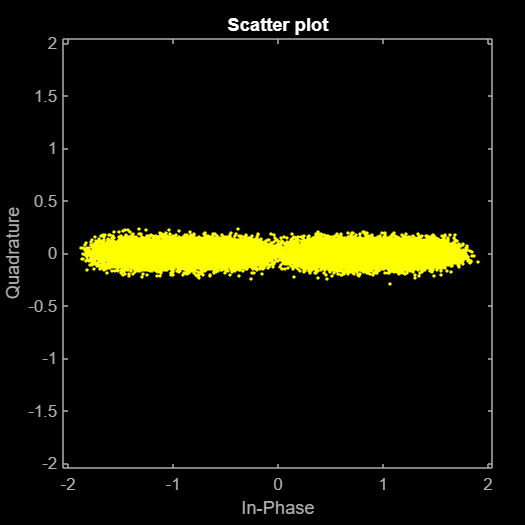

rxSample = rxfilter(rxSig);
scatterplot(rxSample(10000:end),2)

Correct the symbol timing error by using the `symbolSync` object. Display the scatter plot. The synchronized signal now aligns with the expected BPSK constellation.

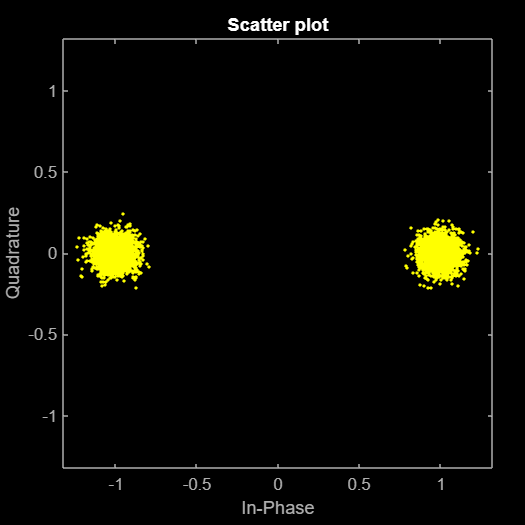

rxSync = symbolSync(rxSample);
scatterplot(rxSync(10000:end),2)

Demodulate the BPSK signal.

recData = pskdemod(rxSync,M);

Compute, in symbols, the total system delay due to the fixed delay and the transmit and receive RRC filters.

sysDelay = dsp.Delay(fixedDelaySym + txfilter.FilterSpanInSymbols/2 + ...
    rxfilter.FilterSpanInSymbols/2);

Compute the BER, taking into account the system delay.

[numErr1,ber1] = biterr(sysDelay(data),recData)

numErr1 = 5

ber1 = 2.5000e-04

*Copyright 2018 The MathWorks, Inc.*